# Feed jitter: structural dynamics simulation model

This live script estimates how much the feed (the receiver hardware held above the dish) shakes in gusty wind, and how that shaking turns into beam pointing error. It sweeps the strut stiffness and the elevation angle and reports two numbers for every case: a statistical RMS and an expected peak (MAX).

**Why it matters.** At sub-THz the wavelength is about 1 mm and the beam is only about 0.8 mrad wide. Losing a tenth of that beamwidth to pointing error already costs signal, so jitter of a few micro-radians matters.

### How to use

Run the whole script with **Run**, or run it section by section from the top. Every section uses variables created in the sections above it. Change inputs only in the Parameters section.

### Prerequisites

Basic statics and vibration (a mass on a spring has natural frequency $\omega_n=\sqrt{k/m}$), matrix algebra, and the idea of a power spectrum. Everything else is introduced where it is used. Numbered references such as [1] point to the References section near the end.

**Modules Requirement: **Controls Toolbox!

### Functions used in this script

These functions live at the bottom of the script - here's a description of each one.

- `buildModel(k, ...)` assembles the whole structure for a given strut stiffness $k$, using parameter *m* as the rigid body feed-truss mass. It incorporates the strut joint springs,and the spring element of the truss, and it computes the modes + modal damping matrix. It then builds the load matrix $B$ and output matrix $F$. It returns `M`, `K`, `C`, `B`, `Fy`, the natural frequencies `fn`, and the dominant feed lateral frequency `f_feed_lat`.

- `addLink(K, ia, Ta, ib, Tb, Kb)` adds a 6×6 spring $K_b$ between 2 points to link 2 bodies or 1 body to the ground (fixed referencE).

- `rigidMap(r)` returns the 6×6 matrix that gives the motion of a point (at offset) [$\mathbf{r}$] on a rigid body: $\mathbf{x}_p=\mathbf{x}+\vec{\theta}\times\mathbf{r}$.

- `skew(r)` builds the cross-product matrix $[\mathbf{r}]_\times$, so that $[\mathbf{r}]_\times\mathbf{v}=\mathbf{r}\times\mathbf{v}$.

- `localAxes(u)` returns the rotation from the dish axes to a strut's own axes, with local $x$ along the strut.

- `windExcite(el, ...)` turns an elevation angle into the five wind load coefficients, for both the fluctuating gust load and the mean-wind load.

## Model at a glance

The structure is a set of masses connected by springs:

- **m1 (feed):** a rigid body that has all 6 degrees of freedom (DOF). Its centre of mass basically sits at height $z_{feed}$ above the dish vertex.

- **Struts:** $n$ identical tubes running from the dish rim to a small ring on m1. Each strut is basically composed of beam elements that have mass and can stretch, bend and twist. A joint spring at each end stands in for the bolted connection.

- **m2 (dish and hub):** another 6-DOF rigid body, with its reference point at the dish vertex. Its CoM is offset from the vertex!

- **Base:** a translational spring $k_{base}$ and a rotational spring $k_{\theta}$ tie m2 to the ground (as in GND, or fixed reference). *The rotational spring element is required - without it the dish could spin freely and the jitter would grow without limit!*

- **Damping:** every vibration mode loses energy at $\zeta=2\%$ of critical damping. (Arbitrary number)

- **Wind:** a turbulent gust $u'(t)$ pushes on both the feed and the dish.

**Coordinates.** Everything is written in the*** dish frame.*** The origin is the dish vertex, $+z$ is the boresight (the direction the dish looks), $x$ is the elevation axis, and $+y$ completes the right-handed set. All motions are small, so the model is linear.

### Equations of motion

$\mathbf{q}$ represents the state displacement and rotation information-bearing vector. Newton's second law for the whole structure becomes a single matrix equation:


$$M\ddot{\mathbf{q}}+C\dot{\mathbf{q}}+K\mathbf{q}=B\mathbf{u},\qquad \mathbf{y}=F\mathbf{q}$$


$M$ holds the masses and inertias, $K$ the spring stiffnesses and $C$ the damping. $B$ says where the loads $\mathbf{u}$ act, and $F$ picks out the outputs $\mathbf{y}$ we care about. The Control System Toolbox object `mechss` stores a model in exactly this second-order form.

clc; clear; close all;

% Control System Toolbox check (mechss, ss, tf, bode, sigma, covar all need it)
if ~license('test', 'Control_Toolbox') || isempty(ver('control')) || ~exist('mechss', 'file')
    error('feed_jitter:noControlToolbox', ...
          'This script requires the Control System Toolbox (mechss, covar, sigma, bode).');
end

## Parameters

All inputs are in SI units and are independent variables. Each function at the bottom of the script takes the values it needs as explicit arguments.

% Feed + sub-reflector (m1): solid cylinder of radius r_feed and length h_feed
m1      = 6.5;                       % [kg]
r_feed  = 0.10;                      % [m] feed body radius
h_feed  = 0.20;                      % [m] feed body length along the boresight
z_feed  = 1.01;                      % [m] feed centre of mass height above the vertex
r_ring  = 0.10;                      % [m] radius of the strut attachment ring on m1

% Dish shell (part of m2): thin paraboloid z = r^2/(4 f_dish), 0 <= r <= r_dish
r_dish     = 1.0;                    % [m] rim radius
f_dish     = 0.91;                   % [m] focal length
thick_dish = 0.0127;                 % [m] shell thickness (0.5 in)
rho_dish   = 1050;                   % [kg/m^3] effective density (placeholder, ~45 kg shell)
z_rim      = r_dish^2/(4*f_dish); % [m] rim height above the vertex

% Hub (part of m2): solid cylinder behind the vertex that tilts with the dish
m_hub  = 45;                         % [kg] mount + hub (tower_tip_mass in macrostructure)
r_hub  = 0.10;                       % [m] hub radius (dish_hub_radius in macrostructure)
h_hub  = 0.20;                       % [m] hub depth (placeholder)
z_hub  = -h_hub/2;                 % [m] hub centre of mass height (negative = behind)

% Struts
n_truss = 3;                         % number of struts
N_el    = 4;                         % beam elements per strut
m_truss = 1.5;                       % [kg] mass of one strut
d_o     = 0.05;                      % [m] tube outer diameter (sets I/A ratio)
t_wall  = 2e-3;                      % [m] tube wall
nu_poisson      = 0.33;                      % [-] Poisson ratio (torsion G = E/2(1+nu))
E_ref   = 69e9;                      % [Pa] aluminium, only for the reference k

% Joints (two per strut, identical). Rotational value near-pinned.
% Strut section properties
d_i      = d_o - 2*t_wall;                   % [m] tube inner diameter
I_truss  = pi/64 * (d_o^4 - d_i^4);          % [m^4]
EI_ref   = E_ref * I_truss;                  % [N m^2]

% Joints (two per strut, identical).
% Stiffnesses scale linearly with strut bending rigidity EI

% Reference values are recovered at EI = EI_ref.
k_joint_ax  = @(EI) 5e7 * (EI ./ EI_ref);     % [N/m] along the strut
k_joint_lat = @(EI) 2e7 * (EI ./ EI_ref);     % [N/m] across the strut
k_joint_rot = @(EI) 1e4 * (EI ./ EI_ref);     % [N m/rad] all three rotations

% Base (m2 to ground) UNK
k_base     = @(EI) 9.75e8 * (EI ./ EI_ref);  % [N/m]
k_base_rot = @(EI) 8.1e8  * (EI ./ EI_ref);  % [N m/rad]
e_base     = 0.30;                          % [m] pivot distance behind vertex

% Damping
zeta = 0.03;

**Wind and Linearization**

Wind force grows with the square of wind speed. We can use Taylor's theorem to linearize the drag force *F. *We split the speed into a mean $\bar{U}$ and a small gust $u'$.


$$F=\frac{1}{2}\rho C_d A(\bar{U}+u')^2\approx\frac{1}{2}\rho C_d A\bar{U}^2+\rho C_d A\bar{U}\,u'$$


The first term is a steady state term while the second is the fluctuating load that actually causes jitter. This quasi-steady split is the standard starting point for gust loading. It drops the small $u'^2$ term and assumes the gust is uniform over each surface. 

With a turbulence intensity of 0.15, a typical gust u' is about 0.15 U, and etc. In this model at least, doubling the gust doubles the load and the jitter. That keeps the whole model linear which is the only way we can model RMS independent of time.

% Wind (linearized drag F = 1/2 rho C A (U+u')^2 ~ mean + rho C A U u')
rho_air = 1.225;                     % [kg/m^3]
U_mean  = 15;                        % [m/s] mean wind
I_u     = 0.25;                      % [-] turbulence intensity, sigma_u = I_u U
L_u     = 30;                        % [m] longitudinal integral length scale
Cd_feed = 1.0;   A_feed = 0.04;    % feed drag coefficient / frontal area [m^2]
C_N     = 1.2;                       % dish normal-force coefficient, face-on
C_S     = 0.3;                       % dish side-force coefficient, edge-on
C_M     = 0.10;                      % dish aero moment coefficient peak (at 45 deg)
A_dish  = pi*r_dish^2;             % [m^2] aperture (projected) area
z_cp    = z_rim/2;                 % [m] centre of pressure above the vertex

% Optics (prime focus): beam deviation factor (Lo) and half-power beamwidth
DoverF4   = (2*r_dish/(4*f_dish))^2;
BDF     = (1 + 0.45*DoverF4)/(1 + DoverF4);
c_tilt  = 0;                         % LOS per rad of feed tilt (~0 prime focus)
rf_Hz   = 225e9;
lambda    = 299792458/rf_Hz;
HPBW      = 1.2*lambda/(2*r_dish);   % [rad]

fd_ratio=f_dish/(2*r_dish)

fd_ratio = 0.4550

**Beam deviation factor (BDF).** When a prime-focus feed moves sideways by $\delta$, the beam tilts by about $\mathrm{BDF}\,\delta/f$, in the opposite direction. A curved reflector steers the beam less than a flat mirror would, so $\mathrm{BDF}<1$. Lo's approximation [1] is $\mathrm{BDF}\approx\frac{1+k_{B}\,(D/4f)^2}{1+(D/4f)^2}$. I used `kB=0.4 `The formula holds for small perturbations. For all intensive purposes, kB selectoin only really changes BDF by +/-5%.

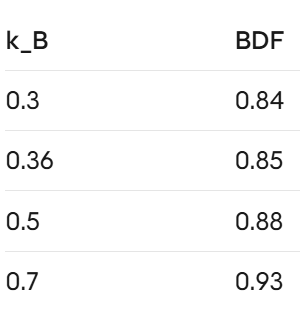

**Some Background... **The dish works like a curved mirror: it gathers the incoming radio waves and focuses them on the feed. If the feed slips sideways, the beam the dish sends out swings the opposite way. With a flat mirror the beam would turn by the full amount of the slip (BDF = 1). A curved dish bends the rays toward its focus, so part of the slip is absorbed and the beam turns by less than a flat mirror would (BDF is below 1). The beam deviation factor is simply that fraction: how much of the full geometric turn you actually get.

disp(BDF);

    0.8725



 For this dish the BDF is about 0.85, so a 1 um sideways slip of the feed tilts the beam by about `0.85 x 1 um / 0.91 m = 0.94 urad`. The script uses this number to convert feed sway into beam pointing error.

**Beamwidth.** The half-power beamwidth (HPBW) is about $1.2\lambda/D$ for a typical tapered illumination (a common approximation). A common pointing budget is **one tenth of it. A **pointing error of HPBW/10 costs about 3% of the on-axis gain.

% Statistics / sweeps
T_expo  = 600;                       % [s] exposure time for peak factor
elev_deg  = [30 45 60 90];                 % elevation angles of interest [deg]
k_vals    = logspace(6, 9, 31);        % strut axial stiffness EA/L [N/m]
f_band    = [0.1 1000];                % [Hz] frequency band for bode / sigma


% Geometry-derived reference values
L_truss = hypot(r_dish - r_ring, z_feed - z_rim);
A_tube  = pi*(d_o^2 - (d_o-2*t_wall)^2)/4;
k_nom   = E_ref*A_tube/L_truss;      % aluminium strut EA/L
fprintf('Strut length %.3f m, reference k (Guess Point) = %.3e N/m, BDF = %.3f\n', ...
        L_truss, k_nom, BDF);

Strut length 1.162 m, reference k (Guess Point) = 1.791e+07 N/m, BDF = 0.872


## Mass properties from geometry

**Feed (m1).** The feed is a solid cylinder of mass $m_1$, radius $r_{feed}$ and length $h_{feed}$, with its axis along the boresight:


$$J_{1,x}=J_{1,y}=\frac{m_1\left(3r_{feed}^2+h_{feed}^2\right)}{12},\qquad J_{1,z}=\frac{m_1 r_{feed}^2}{2}$$


**Dish shell.** The reflector is a thin shell on the paraboloid $z=r^2/(4f)$, out to the rim radius $R$. Cut it into thin rings. A ring at radius $r$ has height $z(r)$ and area


$$dA=2\pi r\sqrt{1+\left(\frac{r}{2f}\right)^2}\,dr$$


We can get the following system parameters by evaluating the integral: 

- area $A=\int dA$ and mass $m_{sh}=\sigma A$;

- centre-of-mass height $\bar{z}_{sh}=\frac{1}{A}\int z\,dA$;

- inertia about the boresight $J_{sh,z}=\sigma\int r^2\,dA$;

- inertia about the $x$ axis through the vertex $J_{sh,x}=\sigma\int\left(\frac{r^2}{2}+z^2\right)dA$

The thin-shell form is accurate when $t\ll R$.

fprintf('R is this times larger than thickness: %.2f > 10 = Valid.', r_dish/thick_dish);

R is this times larger than thickness: 78.74 > 10 = Valid.

**Hub (Dish):** The hub is a solid cylinder of mass $m_{hub}$ whose centre sits at $z_{hub}$ behind the vertex. Its inertias about its own centre use the same cylinder formulas as the feed.

**Combined m2 about the vertex.** The mass and CoM position are $m_2=m_{sh}+m_{hub}$ and $c_2=(m_{sh}\bar{z}_{sh}+m_{hub}z_{hub})/m_2$. The parallel-axis theorem moves the hub inertia to the vertex: $J_{2,x}=J_{sh,x}+J_{hub,x}+m_{hub}z_{hub}^2$ and $J_{2,z}=J_{sh,z}+J_{hub,z}$.

**In plain terms: why combine them. **The dish shell and the hub are assumed here to be one rigid body. m2  = shell mass + hub mass.The balance point is the mass-weighted average of the heights.

Because the vertex is not the centre of mass, the 6×6 mass block of m2 couples translation to rotation: 


$$M_2=\left[\begin{array}{cc}m_2 I & -m_2[\mathbf{c}_2]_\times\\ m_2[\mathbf{c}_2]_\times & J_2\end{array}\right],\qquad \mathbf{c}_2=(0,0,c_2)$$


`What this means:` A sideways push on the dish also makes it tilt, and gravity automatically produces a moment about the vertex.

% Feed: solid cylinder about its own centre of mass
J1 = diag([m1*(3*r_feed^2 + h_feed^2)/12*[1 1], m1*r_feed^2/2]);


% Dish shell: ring area dA(r) and ring height z(r) on the paraboloid
dA    = @(r) 2*pi*r.*sqrt(1 + (r/(2*f_dish)).^2);
zr    = @(r) r.^2/(4*f_dish);
A_sh  = integral(dA, 0, r_dish);                                     % shell area
sig   = rho_dish*thick_dish;                                       % areal density
m_sh  = sig*A_sh;                                                      % shell mass
z_sh  = integral(@(r) zr(r).*dA(r), 0, r_dish)/A_sh;                 % shell CG height
Jz_sh = sig*integral(@(r) r.^2.*dA(r), 0, r_dish);                   % about boresight
Jx_sh = sig*integral(@(r) (r.^2/2 + zr(r).^2).*dA(r), 0, r_dish);    % about x at vertex

% Hub: solid cylinder about its own centre of mass
Jx_hub = m_hub*(3*r_hub^2 + h_hub^2)/12;
Jz_hub = m_hub*r_hub^2/2;

% Combined m2 about the vertex (parallel-axis theorem for the hub)
m2 = m_sh + m_hub;
c2 = (m_sh*z_sh + m_hub*z_hub)/m2;                             % CG height above vertex
Jx2  = Jx_sh + Jx_hub + m_hub*z_hub^2;
J2 = diag([Jx2 Jx2 Jz_sh + Jz_hub]);                                 % about the vertex

disp(table({'m1';'J1_x';'J1_z';'shell area';'shell mass';'shell CG z';'m2';'m2 CG z';'J2_x';'J2_z'}, ...
     [m1; J1(1,1); J1(3,3); A_sh; m_sh; z_sh; m2; c2; J2(1,1); J2(3,3)], ...
     {'kg';'kg m^2';'kg m^2';'m^2';'kg';'m';'kg';'m';'kg m^2 (vertex)';'kg m^2'}, ...
     'VariableNames', {'quantity','value','unit'}));

       quantity        value             unit        
    ______________    ________    ___________________

    {'m1'        }         6.5    {'kg'             }
    {'J1_x'      }    0.037917    {'kg m^2'         }
    {'J1_z'      }      0.0325    {'kg m^2'         }
    {'shell area'}      3.3679    {'m^2'            }
    {'shell mass'}      44.912    {'kg'             }
    {'shell CG z'}     0.14037    {'m'              }
    {'m2'        }      89.912    {'kg'             }
    {'m2 CG z'   }    0.020067    {'m'              }
    {'J2_x'      }      13.353    {'kg m^2 (vertex)'}
    {'J2_z'      }      23.173    {'kg m^2'         }



## Outputs

Every output is measured in the dish frame, so moving the whole antenna rigidly produces no output except dish tilt.

- **Relative feed displacement:** $\mathbf{q}_{rel}=\mathbf{x}_1-(\mathbf{x}_2+\vec{\theta}_2\times\mathbf{r}_1)$, from basic engineering dynamics kinematic theory. $\mathbf{r}_1$ points from the vertex to the feed. The lateral sway $(q_x,q_y)$ mispoints the beam. The axial sway $q_z$ defocuses it (aka: changes the focal length), which lowers gain without adding physical changes (contributing to mechanical error).

- **Feed tilt:** $\vec{\theta}_1-\vec{\theta}_2$, the feed rotating relative to the dish.

- **Dish tilt:** $\vec{\theta}_2$, the whole reflector rotating on its base.

- **Line of sight (LOS):** $\mathrm{LOS}_x=\theta_{2x}+\frac{\mathrm{BDF}}{f}q_y$ and $\mathrm{LOS}_y=\theta_{2y}-\frac{\mathrm{BDF}}{f}q_x$.

**Where the LOS formula comes from >>** For small motions, beam pointing errors from separate sources follow principle of superposition. A rigid rotation of the reflector rotates the beam by the same angle. A lateral feed offset steers the beam by $\mathrm{BDF}\cdot\delta/f$ in the opposite direction [1, 2]. Antenna pointing budgets combine these two terms in exactly this way [3, 4, 5]. The signs differ between the x and y equations because a feed pushed toward $+y$ tilts the beam toward $-y$, which is a positive rotation about $x$. Feed tilt barely moves the beam of a prime-focus antenna, so `c_tilt` is 0. A Cassegrain antenna would need extra terms for the sub reflector.

Some outputs are exactly zero by symmetry. For example, at 0 deg elevation the wind hits the dish face-on, so nothing pushes the feed sideways. The plot helper `clip` hides those round-off values so the log axes stay readable...

% 9 displacement outputs: q_x q_y q_z, tilt_x tilt_y, LOS_x LOS_y, dish_x dish_y.
% They are grouped into 5 reported metrics: lateral sway (outputs 1-2), axial sway (3),
% feed tilt (4-5), LOS (6-7) and dish tilt (8-9). gsum() adds up the outputs of each group.
gsum = @(v) accumarray([1 1 2 3 3 4 4 5 5].', v(:));

% Plot helper: clip() turns values below 1e-6 of ref into NaN for log axes
clip = @(x, ref) x + 0./(x > 1e-6*ref);

## Wind Model Explanation

**We discuss linearizaton of drag in the Parameter section.**

**Gust spectrum.** Real gusts contain many (and realistically unmodelable) frequencies at once. A power spectral density (PSD) describes how the gust's energy is spread over frequency. This script uses the von Kármán spectrum [3] in the form commonly used in wind engineering:


$$S_u(f)=\frac{4\sigma_u^2\,L_u/\bar{U}}{\left(1+70.8\,(fL_u/\bar{U})^2\right)^{5/6}},\qquad \sigma_u=I_u\bar{U}$$


Here $I_u$ is the turbulence intensity and $L_u$ the integral length scale, roughly the size of the largest gusts.

***The von Kármán spectrum*** is a standard engineering curve fitted to real wind measurements near the ground and is a good standard model of turbulent wind / gusts. Its limits are that it describes the gust at a single point,** so it can overstate the load across a large dish...** and it must be approximated by a shaping filter before it can be used in the state-space model.


$$H_0(s)=\frac{1+0.25\,Ts}{1+1.357\,Ts+0.1987\,T^2s^2},\qquad T=L_u/\bar{U}$$


This shaping filter (transfer function) turns white noise, which has equal energy at every frequency, into a gust signal with the von Kármán mix of slow and fast swirls, so the wind can be fed into the state-space model. It starts from a standard second-order fit and emulates real turbulence drops ( f^-5/3 slope ). This model overall works with structure swith < 1 KHz vibration mode.

**Where the numbers in H0(s) come from. **The three numbers 0.25, 1.357 and 0.1987 are fit coefficients that I got from the MATLAB Aerospace Blockset von Karman turbulence block (tabulated numbers following military flying qualities standard) As a check, comparing the filter's power response with the von Karman curve (taking T = 1, for frequencies up to 1/T Hz) gives a difference below 0.15 dB. At higher frequency the filter falls below the curve, by about 2 dB at 10/T Hz, which is what the lead-lag pairs correct.

% Shaping filter: unit-intensity white noise -> u' [m/s]
%   start from the second-order fit H0, T = L_u/U
%   for each decade from 2/T Hz up to 1 kHz: add a zero, and a pole 10^(1/6) higher,
%   which lifts the f^-2 roll-off to von Karman's f^-5/3 (fit within ~1.6 dB)
%   scale so the output variance (covar, Lyapunov) equals (I_u U)^2

Tl  = L_u/U_mean;
Hw  = tf([0.25*Tl 1], [0.1987*Tl^2 1.357*Tl 1]);
fz  = (2/Tl)*10.^(0:ceil(log10(1000*Tl/2)));         % lead-lag zero frequencies [Hz]
for kz = 1:numel(fz)
    wz = 2*pi*fz(kz);
    Hw = Hw*tf([1/wz 1], [1/(wz*10^(1/6)) 1]);
end
Hw  = ss(Hw);
Hw  = Hw*(I_u*U_mean/sqrt(covar(Hw, 1)));

## Build Model + Compute Modes

`buildModel` assembles $M$, $K$ and $C$ for one strut stiffness. The structure itself does not change with elevation; only the wind loads do.

**Strut beam elements.** Each strut piece is a 3D Euler–Bernoulli beam with 12 DOF (6 per end). It can stretch ($EA/L$), twist ($GJ/L$) and bend in two planes (terms in $12EI/L^3$), and its mass is spread along it with the consistent mass matrix.

**Modes.** Solving $K\phi=\omega^2 M\phi$ gives the natural frequencies $\omega_r$ and mode shapes $\phi_r$. Each mode is one way the structure prefers to vibrate.

**Modal damping.** With mass-normalized mode shapes $\Phi$, the matrix C damps every mode at exactly $\zeta$.

**What is sysLoad? **sysLoad is the structure written as a single MATLAB model object (a mechss object from the Control System Toolbox). Think of it as a black box. You put in the five wind loads (feed force in y and z, dish force in y and z, and dish moment about x) and it gives out nine motions: the feed's sideways, axial and tilt motion relative to the dish, the line-of-sight pointing error and the dish tilt. Inside the box are the matrices M, K and C (mass, stiffness and damping), which describe how the structure responds to loads, plus B (where each load is applied) and Fy (which motions to report). The name mechss means the box keeps the equation in its natural second-order form, M q'' + C q' + K q = B u, which is faster for large models than converting it to first-order form. sysLoad is built once, at the reference stiffness. The singular value plot, the mode table and the Bode plots all feed it a frequency and read off how large the motions are. The stiffness sweep does not use it; the sweep rebuilds the model for every stiffness.

mdl = buildModel(k_nom, m1, J1, m2, J2, c2, z_feed, r_ring, r_dish, z_rim, f_dish, ...
    n_truss, N_el, m_truss, d_o, t_wall, nu_poisson, ...
    k_joint_ax(k_nom), k_joint_lat(k_nom), k_joint_rot(k_nom), ...
    k_base(k_nom), k_base_rot(k_nom), e_base, zeta, BDF, c_tilt);
disp(mdl);

             M: [102×102 double]
             K: [102×102 double]
             C: [102×102 double]
             B: [102×5 double]
            Fy: [9×102 double]
            fn: [102×1 double]
    f_feed_lat: 84.5335



disp(mdl);

             M: [102×102 double]
             K: [102×102 double]
             C: [102×102 double]
             B: [102×5 double]
            Fy: [9×102 double]
            fn: [102×1 double]
    f_feed_lat: 84.5335



% Load plant: 5 physical load inputs -> 9 outputs, kept sparse as a mechss
sysLoad = mechss(sparse(mdl.M), sparse(mdl.C), sparse(mdl.K), ...
                 sparse(mdl.B), sparse(mdl.Fy));
sysLoad.InputName  = {'F_feed_y','F_feed_z','F_dish_y','F_dish_z','M_dish_x'};
sysLoad.OutputName = {'q_x','q_y','q_z','tilt_x','tilt_y','LOS_x','LOS_y','dish_x','dish_y'};

% Frequency grid: log grid plus every mode in band, so 2% peaks are resolved
fn = mdl.fn;
w  = 2*pi*unique([logspace(log10(f_band(1)), log10(f_band(2)), 3000), ...
                  fn(fn >= f_band(1) & fn <= f_band(2)).']);

fprintf('Modes in %.1f-%.0f Hz: %d, above band: %d (lowest above: %.0f Hz)\n', ...
        f_band, nnz(fn <= f_band(2)), nnz(fn > f_band(2)), min([fn(fn > f_band(2)); NaN]));

Modes in 0.1-1000 Hz: 21, above band: 81 (lowest above: 1029 Hz)


### Singular values [wip]

Sigma (the singular value) is the plant's gain: how much bigger the output is than the input. With five inputs, the gain depends on how the five loads are combined, so there are several singular values at each frequency. The largest one, sigma-max, is the gain for the worst possible mix of loads at that frequency.

The load plant $G(j\omega)$ maps the five load amplitudes to the feed displacement $\mathbf{q}$. Its largest singular value $\bar{\sigma}(\omega)$ is the largest gain it can have at frequency $\omega$.

**What the plot shows. **Imagine shaking the structure with the five loads at one steady frequency, so the load rises and falls that many times each second. The feed moves back and forth by some amount. Sigma-max is the biggest feed movement you could get for each newton of load, if the five loads are combined in the worst possible way. It is measured in micrometres per newton. A high value means the feed moves a lot at that frequency, and the feed movement is never larger than sigma-max times the size of the load.

**A caution. **Four of the five loads are forces (N) and one is a moment (N m). The calculation treats 1 N m as equal to 1 N, so read sigma-max as a worst-case trend, not an exact number.

**Frequency on this plot. **The horizontal axis is the load frequency: how fast the wind load rises and falls. It is not the structure's own frequency. The dotted vertical lines are the structure's natural frequencies, the rates at which it prefers to vibrate. The curve peaks where the load frequency matches a natural frequency, which is called resonance. The table lists the first 15 natural frequencies with sigma-max at each one. A mode with a small value barely moves the feed, however low its frequency.

sv = sigma(sysLoad(1:3,:), w);                       % load -> q only (metres)

% Mode table with the worst-case load -> q gain at each mode frequency
nShow  = min(15, numel(fn));
svMode = sigma(sysLoad(1:3,:), 2*pi*fn(1:nShow));
disp(table((1:nShow).', fn(1:nShow), 1e6*svMode(1,:).', ...
     'VariableNames', {'Mode number','Natural frequency [Hz]','Worst-case feed motion [um per N]'}));

    Mode number    Natural frequency [Hz]    Worst-case feed motion [um per N]
    ___________    ______________________    _________________________________

         1                 84.533                          1.9894             
         2                 84.533                          1.9894             
         3                 95.712                         0.36609             
         4                  175.7                        0.097808             
         5                 178.77                        0.069495             
         6                 178.77                        0.069495             
         7                 223.86                         0.51307             
         8                 223.86                         0.51307             
         9                 272.39                         0.70011             
        10                 2

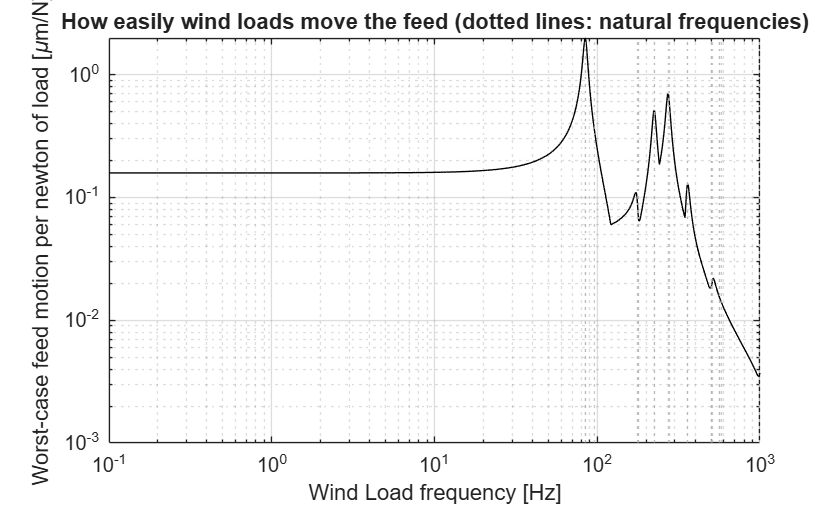

figure('Name','sigma');
loglog(w/2/pi, sv(1,:)*1e6, 'k'); hold on;
xline(fn(fn <= f_band(2)), ':', 'Color', [0.7 0.7 0.7]);
grid on;
xlabel('Wind Load frequency [Hz]');
ylabel('Worst-case feed motion per newton of load [\mum/N]');
title('How easily wind loads move the feed (dotted lines: natural frequencies)');

Note: each dotted vertical line marks one natural frequency (one mode) of the structure.

### Modal Analysis

G      = sysLoad(1:3,:);
loadNames = {'Feed force y [N]','Feed force z [N]','Dish force y [N]','Dish force z [N]','Dish moment about x [N m]'};
nShow  = min(15, numel(fn));

worstMix = zeros(5, nShow);     % |load| weights, unit norm per mode
worstPhs = zeros(5, nShow);     % phases [deg]
sigmaMax = zeros(1, nShow);
for m = 1:nShow
    Gw = squeeze(freqresp(G, 2*pi*fn(m)));
    [~, S, V] = svd(Gw);
    sigmaMax(m)   = S(1,1);
    worstMix(:,m) = abs(V(:,1));
    worstPhs(:,m) = angle(V(:,1))*180/pi;
end

% Table: one row per natural frequency (mode), one column per load, showing the relative weight
% (1 = the whole worst-case load comes from that one load)
disp(array2table(worstMix.', 'VariableNames', loadNames, ...
    'RowNames', compose('Mode %d (%.1f Hz)', (1:nShow).', fn(1:nShow))));

                          Feed force y [N]    Feed force z [N]    Dish force y [N]    Dish force z [N]    Dish moment about x [N m]
                          ________________    ________________    ________________    ________________    _________________________

    Mode 1 (84.5 Hz)                  1          1.0859e-12          1.6997e-06          8.1711e-18              1.5195e-06        
    Mode 2 (84.5 Hz)                  1          8.0935e-13          1.6997e-06          6.1955e-18              1.5195e-06        
    Mode 3 (95.7 Hz)                  1          1.0317e-12          2.3194e-06          9.3725e-18              2.0254e-06        
    Mode 4 (175.7 Hz)        3.8689e-11                   1          5.1392e-16          7.8488e-06  

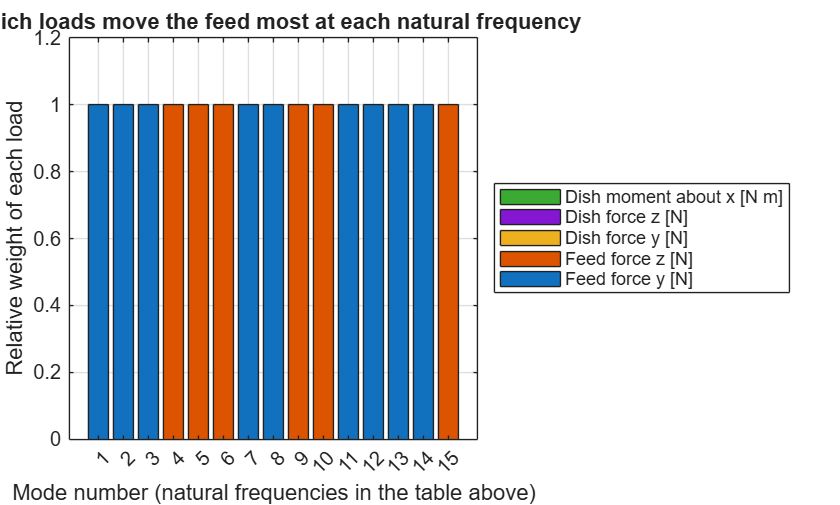

% Bar chart: stacked load weights per mode
figure('Name','worst-case load mix');
bar(worstMix.', 'stacked');
xlabel('Mode number (natural frequencies in the table above)'); ylabel('Relative weight of each load');
legend(loadNames, 'Location', 'eastoutside'); grid on;
title('Which loads move the feed most at each natural frequency');

### Bode magnitude per unit gust

A Bode magnitude plot shows how strongly a system responds to a sinusoidal input at each frequency so that we can find the **worst-case frequency**.

 Here the input is the gust $u'$, so the curve is $|y(j\omega)/u'(j\omega)|$: the output amplitude per 1 m/s of gust, plotted against frequency on log axes. One curve is drawn per elevation.

**Frequency on these plots. **The horizontal axis is the gust frequency: how fast the wind speed rises and falls. It is the input, not the structure's own frequency. The peaks appear where the gust frequency matches one of the structure's natural frequencies.

One figure is drawn for each of four different outputs:

- **Lateral sway,** $q_y$: the feed moving relative to the dish along $y$. **This is the mechanical pointing error #1.**

- **Axial sway,** $q_z$: the feed moving along the boresight. This is the defocus term, **which costs gain** but does not move the beam.

- **Feed tilt,** $\mathrm{tilt}_x$: the feed rotating relative to the dish about the elevation axis.** Mechanical pointing error #2.**

- **Line of sight,** $\mathrm{LOS}_x$: the resulting beam pointing error about $x$. It combines dish tilt $\theta_{2x}$ with $(\mathrm{BDF}/f)\,q_y$, so it can show peaks from both the feed modes and the dish modes.

**How to read the plots? >> **The flat region at low frequency is quasi-static. The peaks are resonances, amplified by roughly $1/(2\zeta)=25$. [UNK] A curve is missing where that output is zero by symmetry, such as $q_y$ at 0 deg elevation, where the wind is purely axial. UNK

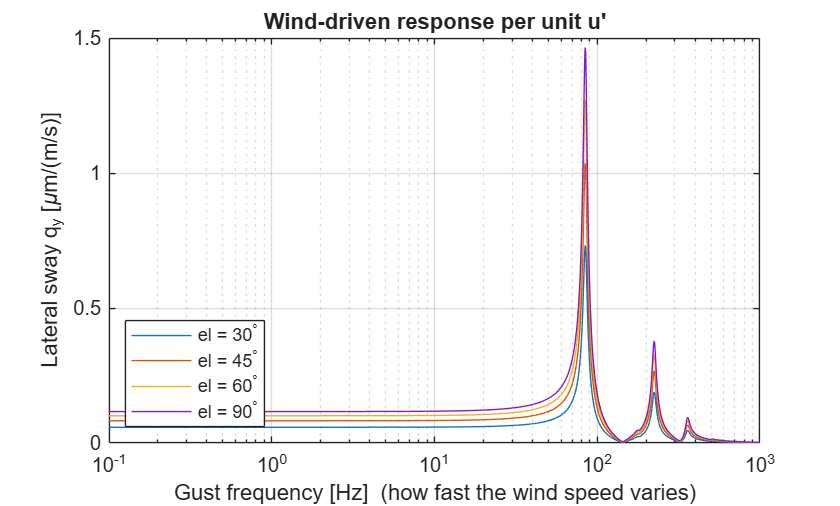

% Loop: for each elevation, scale the load plant by the wind influence vector
%       and store |output / u'| over the frequency grid
mag = zeros(9, numel(w), numel(elev_deg));
for ie = 1:numel(elev_deg)
    bw   = windInfluence(deg2rad(elev_deg(ie)), Cd_feed, A_feed, C_S, A_dish, C_N, z_cp, r_dish, C_M, rho_air, U_mean);
    sysW = sysLoad*bw;                               % mechss, input = u'
    mag(:,:,ie) = squeeze(bode(sysW, w));            % 9 x nw
end

% One figure per output, one curve per elevation (symmetry zeros clipped)
figure('Name','bode lateral sway');
semilogx(w/2/pi, 1e6*clip(squeeze(mag(2,:,:)), max(mag(2,:,:), [], 'all'))); grid on;
xlabel('Gust frequency [Hz]  (how fast the wind speed varies)'); ylabel('Lateral sway q_y [\mum/(m/s)]'); title('Wind-driven response per unit u''');
legend(compose('el = %d^\\circ', elev_deg), 'Location', 'southwest');

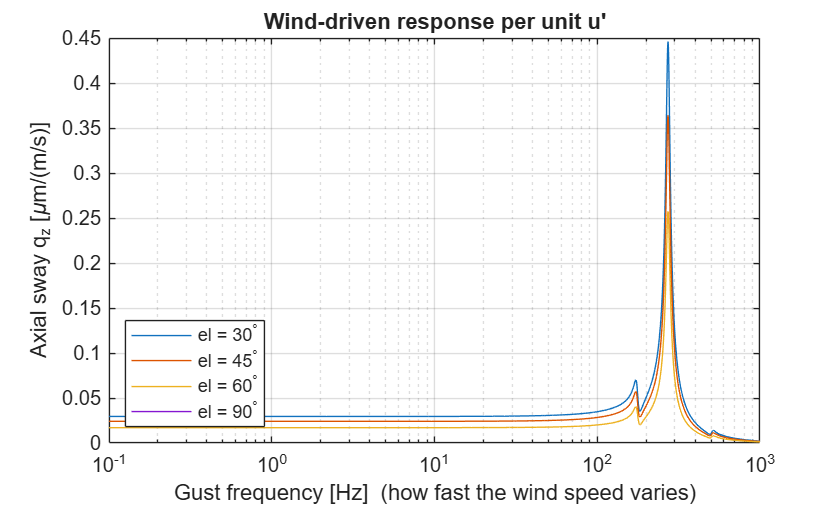


figure('Name','bode axial sway');
semilogx(w/2/pi, 1e6*clip(squeeze(mag(3,:,:)), max(mag(3,:,:), [], 'all'))); grid on; % change it to loglog if you want log-y axis.
xlabel('Gust frequency [Hz]  (how fast the wind speed varies)'); ylabel('Axial sway q_z [\mum/(m/s)]'); title('Wind-driven response per unit u''');
legend(compose('el = %d^\\circ', elev_deg), 'Location', 'southwest');

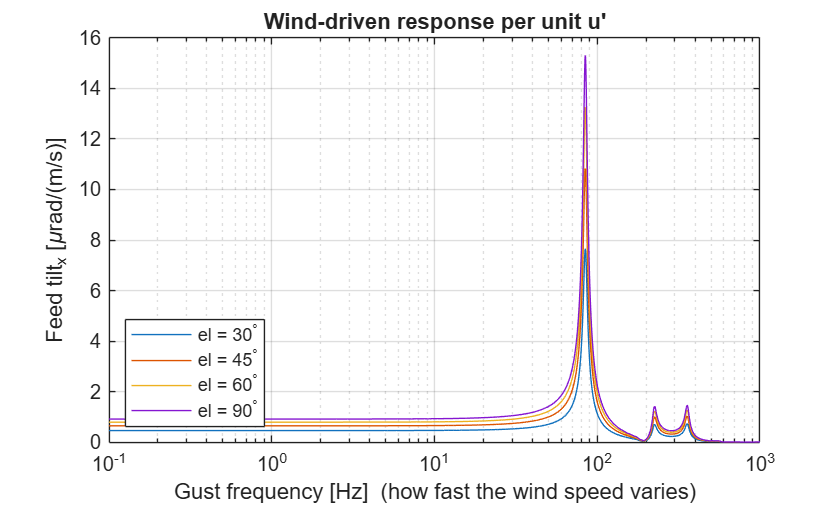


figure('Name','bode feed tilt');
semilogx(w/2/pi, 1e6*clip(squeeze(mag(4,:,:)), max(mag(4,:,:), [], 'all'))); grid on;
xlabel('Gust frequency [Hz]  (how fast the wind speed varies)'); ylabel('Feed tilt_x [\murad/(m/s)]'); title('Wind-driven response per unit u''');
legend(compose('el = %d^\\circ', elev_deg), 'Location', 'southwest');

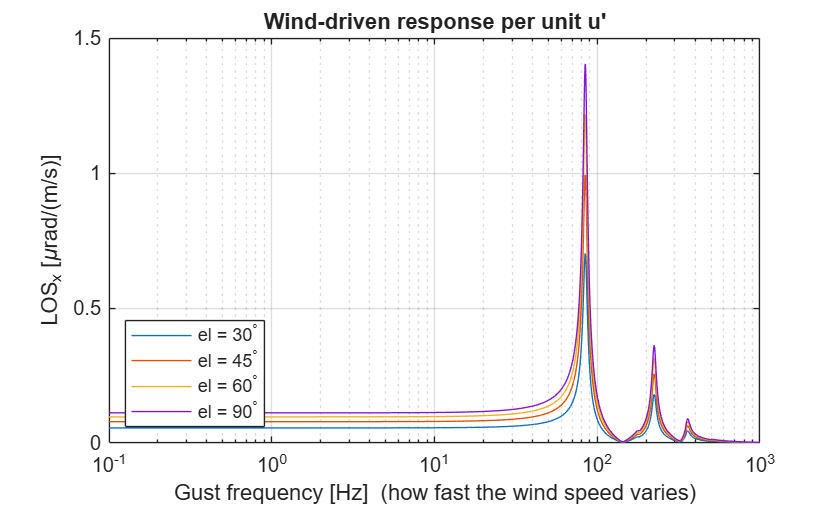


figure('Name','bode LOS');
semilogx(w/2/pi, 1e6*clip(squeeze(mag(6,:,:)), max(mag(6,:,:), [], 'all'))); grid on;
xlabel('Gust frequency [Hz]  (how fast the wind speed varies)'); ylabel('LOS_x [\murad/(m/s)]'); title('Wind-driven response per unit u''');
legend(compose('el = %d^\\circ', elev_deg), 'Location', 'southwest');

% TODO: RETRIEVE WORST CASE FOR EACH ELEVATION - ANGLE / DISPLACEMENT?

### Check the gust spectrum

This plot checks the wind model. It shows how the energy of the gusts is spread over frequency. The horizontal axis is the gust frequency: how fast the wind speed changes. A slow swell of wind is about 0.01 Hz and a quick flutter is 10 Hz or more. It is not the structure's natural frequency. The vertical axis, S_u in (m/s)^2 per Hz, is the gust power spectral density: how much gust energy sits at each frequency. The area under the curve is the total gust variance, the square of the RMS gust speed.

- **Flat part, at low frequency: **slow changes from the biggest swirls of air, about the size of the length scale L_u. They carry the most energy.

- **Corner: **the bend where the curve starts to fall, near 0.06 Hz for the default inputs.

- **Sloping part: **the energy falls steadily at high frequency (the f^-5/3 slope). It is small, but it is the energy that reaches the structure's vibration modes at 15 to 1000 Hz.

**Where the model comes from. **The black curve is the von Karman turbulence model. It comes from Theodore von Karman's 1948 statistical theory of turbulence [3], which describes how the energy of turbulent air is shared between big and small swirls. This script does not derive the formula; it takes it from the literature. The one-direction (along-wind) version used here, with the constant 70.8 and the 5/6 power, is the standard wind-engineering form of that model, fitted to measured atmospheric turbulence. That makes it a fit to real wind, not the turbulence itself.

**How to read the check. **The red dashed curve is what the shaping filter actually sends into the structure model. Where it follows the black curve, the filter is a faithful stand-in for the real wind. Look closely at the high-frequency end, because that is where the structure's modes are. The closer the curves agree there, the more trustworthy the RMS results.

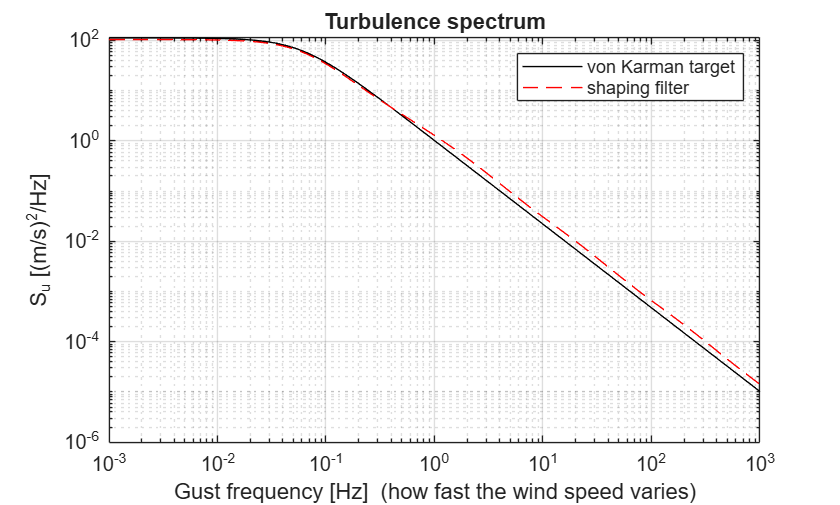

fW    = logspace(-3, log10(f_band(2)), 500);
sig_u = I_u*U_mean;
S_vk  = 4*sig_u^2*Tl ./ (1 + 70.8*(fW*Tl).^2).^(5/6);    % one-sided, per Hz
S_H   = 2*squeeze(abs(freqresp(Hw, 2*pi*fW))).'.^2;      % filter output, per Hz

figure('Name','wind PSD');
loglog(fW, S_vk, 'k', fW, S_H, 'r--'); grid on;
xlabel('Gust frequency [Hz]  (how fast the wind speed varies)'); ylabel('S_u [(m/s)^2/Hz]');
legend('von Karman target','shaping filter'); title('Turbulence spectrum');

## Sweep: static offsets, statistical RMS and peak MAX [wip]

This section runs the full calculation. For each strut stiffness and each elevation angle it produces two kinds of answer: a steady offset (how far constant wind and gravity push the feed and hold it) and two measures of shaking caused by gusts, the RMS and the expected peak (MAX). They are explained next, followed by how each one is computed.

**What is RMS? **RMS (root mean square) is the typical size of the shaking. Wind makes the feed move back and forth in a random way. RMS works like an average distance from the resting position: square every movement, average the squares, then take the square root. If the feed shakes with an RMS of 1 micrometre, it spends most of the time within a few micrometres either side of rest.

**What is MAX? **MAX is the biggest excursion you should expect during an exposure time T (600 s by default). Randomly shaking things occasionally reach values well above their RMS, so MAX is larger than RMS. In the script, MAX equals the mean-wind offset plus g times the RMS, where g is the peak factor, typically about 4 to 5 for the default exposure time.

**The difference. **RMS tells you how the feed behaves most of the time. MAX tells you the worst moment during the exposure. Use RMS to judge the signal lost to continuous jitter, and MAX to judge whether a worst-case gust could push the pointing error past the budget.

**How each is computed. **Three steps, repeated for every stiffness and elevation.

**1. Static offsets. **A static offset is the steady displacement the structure settles into under loads that do not change: the mean wind and gravity. Nothing is shaking, so mass and damping play no part, and the offset comes from the stiffness equation below.


$$K\mathbf{x}_{static}=\mathbf{F}_{static}$$


At elevation angle e, gravity pulls along the direction -(cos e in y, sin e in z) in the dish frame. The gravity load is the mass matrix times g on every translational degree of freedom, which also gives the correct moment from the dish's centre-of-mass offset.

- **Gravity sag **repeats exactly at each elevation, so a pointing model or the focus and feed alignment can calibrate it out. It is reported but not counted as jitter.

- **The mean-wind offset **changes with wind speed and direction over minutes, so a static pointing model cannot remove it. It is added to MAX.

**2. RMS (Lyapunov equation). **To get the RMS without running a time simulation, the script uses the Lyapunov equation. The structure and the shaping filter together form one system driven by white noise, written in state-space form. For a stable system, the average motion settles to a steady spread, called the covariance P, which satisfies the equation below. The RMS of each output is the square root of the diagonal of C P C-transpose. MATLAB's covar solves it. The answer is exact for this linear model, with no time stepping and no frequency grid. The noise strength is 1, because the filter is already scaled to the gust RMS.


$$AP+PA^{T}+BWB^{T}=0$$


**3. Peak MAX. **First, count how often the shaking crosses zero going upward, the rate nu0. A feed that vibrates faster crosses more often, so it gets more chances to reach a large value. The rate comes from the same covariance: nu0 = (1/2 pi) times the RMS velocity divided by the RMS displacement. Second, over the exposure time T there are nu0 times T chances. The expected largest peak is g times the RMS above the offset, where g grows slowly as the number of chances grows:


$$g=\sqrt{2\ln(\nu_0 T)}+\frac{0.5772}{\sqrt{2\ln(\nu_0 T)}}$$


Then MAX = mean-wind offset + g times RMS. This assumes the shaking is random with a bell-curve (Gaussian) spread, which holds for a linear model driven by filtered gusts.

Metrics with x and y parts combine them, for example $\sigma_{lat}=\sqrt{\sigma_x^2+\sigma_y^2}$.

% For every (k, elevation):
%   build M, C, K for this k (once per k; loads change with elevation)
%   static offsets: solve K x = F for mean wind and for gravity
%   stochastic: plant (displacement + velocity outputs) in series with the
%     shaping filter; output covariance from the Lyapunov equation (covar)
%   per metric: sigma, zero-upcrossing rate nu, peak factor g(nu*T),
%     MAX = |mean-wind offset| + g * sigma
nk = numel(k_vals); ne = numel(elev_deg); ng = 5;   % 5 reported metrics
RMS = nan(nk, ne, ng); MAX = RMS; MEANW = RMS; GRAV = RMS; NU = RMS;
f_lat = nan(nk,1);                                   % dominant feed-lateral mode

for ik = 1:nk
    mdl = buildModel(EI, m1, J1, m2, J2, c2, z_feed, r_ring, r_dish, z_rim, f_dish, ...
        n_truss, N_el, m_truss, d_o, t_wall, nu_poisson, ...
        k_joint_ax(EI), k_joint_lat(EI), k_joint_rot(EI), ...
        k_base(EI), k_base_rot(EI), e_base, zeta, BDF, c_tilt);
    f_lat(ik) = mdl.f_feed_lat;

    % Dense first-order form, reused for every elevation (input = 5 loads)
    nd = size(mdl.M,1);
    A  = [zeros(nd) eye(nd); -mdl.M\mdl.K  -mdl.M\mdl.C];
    BL = [zeros(nd,5); mdl.M\mdl.B];
    Cy = blkdiag(mdl.Fy, mdl.Fy);                    % [displacement; velocity] outputs

    for ie = 1:ne
        el       = deg2rad(elev_deg(ie));
        [bw, fm] = windInfluence(el, Cd_feed, A_feed, C_S, A_dish, C_N, z_cp, r_dish, C_M, rho_air, U_mean);

        % Static offsets (dish frame). Gravity load = M * (g on every translational DOF).
        g_vec  = -9.81*[0; cos(el); sin(el)];
        Fg     = mdl.M*repmat([g_vec; 0; 0; 0], nd/6, 1);
        y_wind = mdl.Fy*(mdl.K\(mdl.B*fm));
        y_grav = mdl.Fy*(mdl.K\Fg);

        % Turbulent response covariance via Lyapunov
        sysT = ss(A, BL*bw, Cy, 0)*Hw;               % white noise -> [y; ydot]
        Pc   = covar(sysT, 1);
        varY = diag(Pc(1:9,1:9));  varV = diag(Pc(10:18,10:18));

        % Reduce the 9 outputs to the 5 reported metrics: RMS, peak factor, MAX
        sig  = sqrt(gsum(varY));                          % RMS of each metric
        nu   = sqrt(gsum(varV))./(2*pi*sig);              % zero-upcrossing rate
        xpk  = sqrt(2*log(max(nu*T_expo, exp(1))));       % guarded for small nu*T
        mw   = sqrt(gsum(y_wind.^2));                     % mean-wind offset size
        RMS(ik,ie,:)   = sig;
        NU(ik,ie,:)    = nu;
        MEANW(ik,ie,:) = mw;
        GRAV(ik,ie,:)  = sqrt(gsum(y_grav.^2));
        MAX(ik,ie,:)   = mw + (xpk + 0.5772./xpk).*sig;
    end
    fprintf('%2d/%2d  k = %.2e N/m  f_feed,lat = %6.1f Hz  RMS LOS(el=%d) = %.3g urad\n', ...
            ik, nk, k_vals(ik), f_lat(ik), elev_deg(end), 1e6*RMS(ik,end,4));
end

Unrecognized function or variable 'EI'.

## Results vs strut stiffness

Solid lines are RMS and dashed lines are MAX, with one colour per elevation. The dotted vertical line marks the aluminium tube's stiffness. On the LOS figure, the red dash-dot line is the HPBW/10 pointing budget. A separate figure shows the dominant natural frequency of the feed moving sideways.

**Reading the curves.** Where a curve flattens out, the struts are no longer the weak link. The joints or the base now limit the response, and stiffer struts stop helping.

% One figure per metric: RMS (solid) and MAX (dashed), one colour per elevation
jt = sprintf('Turbulent jitter, U = %g m/s, I_u = %.2f, T = %g s', U_mean, I_u, T_expo);

figure('Name','jitter lateral sway');
ref = max(MAX(:,:,1), [], 'all');
loglog(k_vals, 1e6*clip(RMS(:,:,1), ref), '-'); hold on; set(gca, 'ColorOrderIndex', 1);
loglog(k_vals, 1e6*clip(MAX(:,:,1), ref), '--');
xline(k_nom, 'k:', 'Guess Point'); grid on; axis tight; ylim(ylim.*[0.5 2]);
xlabel('Strut stiffness k = EA/L [N/m]'); ylabel('Lateral sway [\mum]'); title(jt);
legend([compose('RMS el=%d', elev_deg), compose('MAX el=%d', elev_deg), {'Guess Point'}], 'Location', 'southwest');

xlim([2.7051e+05, 2.9476e+09])
ylim([1.5559e-02, 7.0273e+01])
zlim([-1.0000e+00, 1.0000e+00])

figure('Name','jitter axial sway');
ref = max(MAX(:,:,2), [], 'all');
loglog(k_vals, 1e6*clip(RMS(:,:,2), ref), '-'); hold on; set(gca, 'ColorOrderIndex', 1);
loglog(k_vals, 1e6*clip(MAX(:,:,2), ref), '--');
xline(k_nom, 'k:', 'Guess Point'); grid on; axis tight; ylim(ylim.*[0.5 2]);
xlabel('Strut stiffness k = EA/L [N/m]'); ylabel('Axial sway [\mum]'); title(jt);
legend([compose('RMS el=%d', elev_deg), compose('MAX el=%d', elev_deg), {'AGuess Point'}], 'Location', 'southwest');

figure('Name','jitter feed tilt');
ref = max(MAX(:,:,3), [], 'all');
loglog(k_vals, 1e6*clip(RMS(:,:,3), ref), '-'); hold on; set(gca, 'ColorOrderIndex', 1);
loglog(k_vals, 1e6*clip(MAX(:,:,3), ref), '--');
xline(k_nom, 'k:', 'Guess Point'); grid on; axis tight; ylim(ylim.*[0.5 2]);
xlabel('Strut stiffness k = EA/L [N/m]'); ylabel('Feed tilt [\murad]'); title(jt);
legend([compose('RMS el=%d', elev_deg), compose('MAX el=%d', elev_deg), {'Guess Point'}], 'Location', 'southwest');
figure('Name','jitter LOS');
ref = max(MAX(:,:,4), [], 'all');
loglog(k_vals, 1e6*clip(RMS(:,:,4), ref), '-'); hold on; set(gca, 'ColorOrderIndex', 1);
loglog(k_vals, 1e6*clip(MAX(:,:,4), ref), '--');
xline(k_nom, 'k:', 'Guess Point'); yline(1e6*HPBW/10, 'r-.', 'HPBW/10');
grid on; axis tight; ylim(ylim.*[0.5 2]);
xlabel('Strut stiffness k = EA/L [N/m]'); ylabel('LOS pointing [\murad]'); title(jt);
legend([compose('RMS el=%d', elev_deg), compose('MAX el=%d', elev_deg), {'Guess Point', 'HPBW/10'}], 'Location', 'southwest');
figure('Name','jitter dish tilt');
ref = max(MAX(:,:,5), [], 'all');
loglog(k_vals, 1e6*clip(RMS(:,:,5), ref), '-'); hold on; set(gca, 'ColorOrderIndex', 1);
loglog(k_vals, 1e6*clip(MAX(:,:,5), ref), '--');
xline(k_nom, 'k:', 'Guess Point'); grid on; axis tight; ylim(ylim.*[0.5 2]);
xlabel('Strut stiffness k = EA/L [N/m]'); ylabel('Dish tilt [\murad]'); title(jt);
legend([compose('RMS el=%d', elev_deg), compose('MAX el=%d', elev_deg), {'Guess Point'}], 'Location', 'southwest');
% Feed-lateral mode vs. k
figure('Name','feed lateral mode vs k');
semilogx(k_vals, f_lat, 'k'); xline(k_nom, 'k:');
xlabel('Strut stiffness k [N/m]'); ylabel('Natural frequency of the feed sideways mode [Hz]'); grid on;

### Static offsets

A static offset is the steady push the structure settles into under loads that do not change: the mean wind and gravity. It is not jitter, because nothing is shaking. Think of a diving board with a person standing still on the end: it bends down a fixed amount and stays there.

The figures show how far the feed is displaced sideways (lateral sway) and along the boresight (axial sway), in micrometres, as the struts get stiffer. Solid lines are the offset from the mean wind and dashed lines are the sag from gravity, with one colour per elevation angle. Both come from the stiffness equation K x = F, so stiffer struts give smaller offsets. Use them to check feed alignment and focus budgets, and to confirm that the displacements stay small enough for the linear model to hold, since the model assumes small motions.

% Static offsets: solid = mean wind, dashed = gravity, one colour per elevation
figure('Name','static lateral sway');
ref = max([MEANW(:,:,1) GRAV(:,:,1)], [], 'all');
loglog(k_vals, 1e6*clip(MEANW(:,:,1), ref), '-'); hold on; set(gca, 'ColorOrderIndex', 1);
loglog(k_vals, 1e6*clip(GRAV(:,:,1), ref), '--');
xline(k_nom, 'k:'); grid on; xlabel('Strut stiffness k [N/m]');
ylabel('Lateral sway, static [\mum]'); title('solid: mean wind, dashed: gravity');

figure('Name','static axial sway');
ref = max([MEANW(:,:,2) GRAV(:,:,2)], [], 'all');
loglog(k_vals, 1e6*clip(MEANW(:,:,2), ref), '-'); hold on; set(gca, 'ColorOrderIndex', 1);
loglog(k_vals, 1e6*clip(GRAV(:,:,2), ref), '--');
xline(k_nom, 'k:'); grid on; xlabel('Strut stiffness k [N/m]');
ylabel('Axial sway, static [\mum]'); title('solid: mean wind, dashed: gravity');

## References

Citations are journal articles. Check them against the originals before formal use.

- [1] Y. T. Lo, "On the beam deviation factor of a parabolic reflector," IRE Transactions on Antennas and Propagation, vol. 8, no. 3, pp. 347–349, 1960.

- [2] J. Ruze, "Lateral-feed displacement in a paraboloid," IEEE Transactions on Antennas and Propagation, vol. 13, no. 5, pp. 660–665, 1965.

- [3] T. von Kármán, "Progress in the statistical theory of turbulence," Proceedings of the National Academy of Sciences, vol. 34, no. 11, pp. 530–539, 1948.

## Local functions

These are described in **Functions used in this script** at the top.

function mdl = buildModel(k_truss, m1, J1, m2, J2, c2, z_feed, r_ring, r_dish, z_rim, f_dish, ...
                  n_truss, N_el, m_truss, d_o, t_wall, nu_poisson, k_joint_ax, k_joint_lat, k_joint_rot, ...
                  k_base, k_base_rot, e_base, zeta, BDF, c_tilt)
% Assemble M, K, modal C, load matrix B and output matrix Fy for one strut stiffness.
%   allocate 6 DOF for m1, m2 and every strut node
%   put the rigid-body mass blocks of m1 (at its CG) and m2 (at the vertex,
%   with its CG offset c2 coupling translation and rotation) on the diagonal
%   build one beam element in local axes (same for every element)
%   for each strut:
%       place it from the rim (angle phi) to the ring on m1
%       rotate the element to the strut direction and stamp N_el copies
%       stamp a joint bushing rim->first node and last node->m1 ring
%   stamp the base spring from the m2 pivot to ground
%   modal decomposition, then C = M V diag(2 zeta w) V' M  (mass-normalized V)
%   build load (B) and output (Fy) selection matrices
    nNode = N_el + 1;
    ndof  = 12 + n_truss*nNode*6;
    K = zeros(ndof); M = zeros(ndof);
    M(1:6,1:6)   = blkdiag(m1*eye(3), J1);                 % m1 about its CG
    cx = skew([0; 0; c2]);                                    % m2 CG offset from vertex
    M(7:12,7:12) = [m2*eye(3), -m2*cx; m2*cx, J2];      % m2 about the vertex
    i1 = 1:6; i2 = 7:12;                                        % m1, m2 DOF indices

    % Strut section: k_truss sets E for the fixed tube; m_truss sets density
    L   = hypot(r_dish - r_ring, z_feed - z_rim);
    Le  = L/N_el;
    A   = pi*(d_o^2 - (d_o-2*t_wall)^2)/4;
    I   = pi*(d_o^4 - (d_o-2*t_wall)^4)/64;
    J   = 2*I;
    E   = k_truss*L/A;  G = E/(2*(1+nu_poisson));
    rho = m_truss/(A*L);
    me  = rho*A*Le;                                  % element mass

    % 12x12 Euler-Bernoulli 3D frame element, consistent mass, local axes.
    %   local DOF order per node: [u v w thx thy thz]
    %   axial and torsion: 2-node bar; bending in x-y and x-z planes: Hermite cubic
    %   (x-z plane uses the sign-flipped coupling because dw/dx = -thy)
    Kl = zeros(12); Ml = zeros(12);
    bar = [1 -1; -1 1]; cbar = [2 1; 1 2]/6;
    Kl([1 7],[1 7])   = E*A/Le*bar;   Ml([1 7],[1 7])   = me*cbar;
    Kl([4 10],[4 10]) = G*J/Le*bar;   Ml([4 10],[4 10]) = rho*J*Le*cbar;
    kb = E*I/Le^3*[12 6*Le -12 6*Le; 6*Le 4*Le^2 -6*Le 2*Le^2; ...
                   -12 -6*Le 12 -6*Le; 6*Le 2*Le^2 -6*Le 4*Le^2];
    mb = me/420*[156 22*Le 54 -13*Le; 22*Le 4*Le^2 13*Le -3*Le^2; ...
                 54 13*Le 156 -22*Le; -13*Le -3*Le^2 -22*Le 4*Le^2];
    S  = diag([1 -1 1 -1]);
    iy = [2 6 8 12]; iz = [3 5 9 11];
    Kl(iy,iy) = kb;      Ml(iy,iy) = mb;
    Kl(iz,iz) = S*kb*S;  Ml(iz,iz) = S*mb*S;

    r1 = [0; 0; z_feed];                           % m1 reference point (its CG)

    % Loop: assemble each strut and its two joints
    for i = 1:n_truss
        phi   = 2*pi*(i-1)/n_truss;
        p_bot = [r_dish*cos(phi); r_dish*sin(phi); z_rim];
        p_top = [r_ring*cos(phi); r_ring*sin(phi); z_feed];
        u     = (p_top - p_bot)/L;                   % strut axis, rim -> feed
        lam   = localAxes(u);
        nodeIdx = @(j) 12 + ((i-1)*nNode + (j-1))*6 + (1:6);

        % Element matrices rotated to the dish frame
        T  = kron(eye(4), lam);
        Ke = T.'*Kl*T;  Me = T.'*Ml*T;

        % Loop: stamp beam elements along the strut
        for e = 1:N_el
            idx = [nodeIdx(e) nodeIdx(e+1)];
            K(idx,idx) = K(idx,idx) + Ke;
            M(idx,idx) = M(idx,idx) + Me;
        end

        % Joint bushing: axial/lateral stiffness about the strut axis, isotropic rotation
        Kj = blkdiag(lam.'*diag([k_joint_ax k_joint_lat k_joint_lat])*lam, ...
                     k_joint_rot*eye(3));
        K  = addLink(K, i2, rigidMap(p_bot), nodeIdx(1), eye(6), Kj);          % rim joint
        K  = addLink(K, nodeIdx(nNode), eye(6), i1, rigidMap(p_top - r1), Kj); % feed joint
    end

    % Base: translational k_base + rotational k_base_rot at the pivot, to ground
    Kbase = blkdiag(k_base*eye(3), k_base_rot*eye(3));
    K = addLink(K, i2, rigidMap([0; 0; -e_base]), [], [], Kbase);
    K = (K + K.')/2;  M = (M + M.')/2;

    % Modes and explicit 2% modal damping
    [V, D] = eig(K, M);
    [w2, ord] = sort(diag(D)); V = V(:,ord);
    V  = V ./ sqrt(diag(V.'*M*V)).';                 % mass-normalize
    wn = sqrt(max(w2, 0));
    C  = M*V*diag(2*zeta*wn)*V.'*M;  C = (C + C.')/2;

    % Load inputs: [F_feed_y F_feed_z F_dish_y F_dish_z M_dish_x]
    B = zeros(ndof, 5);
    B(2,1) = 1; B(3,2) = 1; B(8,3) = 1; B(9,4) = 1; B(10,5) = 1;

    % Outputs: q = x1 - x2 + skew(r1) theta2  (= x1 - (x2 + theta2 x r1))
    Q  = zeros(3,ndof); Q(:,1:3) = eye(3); Q(:,7:9) = -eye(3); Q(:,10:12) = skew(r1);
    Tt = zeros(2,ndof); Tt(:,4:5) = eye(2); Tt(:,10:11) = -eye(2);   % feed tilt
    Th = zeros(2,ndof); Th(:,10:11) = eye(2);                        % dish tilt
    % LOS: dish rotation + beam deviation from lateral feed offset (opposite sense)
    LOSx = Th(1,:) + BDF/f_dish*Q(2,:) + c_tilt*Tt(1,:);
    LOSy = Th(2,:) - BDF/f_dish*Q(1,:) + c_tilt*Tt(2,:);
    Fy   = [Q; Tt; LOSx; LOSy; Th];

    % Dominant feed-lateral mode: largest modal contribution to the static
    % q_y response under a lateral feed force, (Q_y phi)(phi' b) / w^2
    contrib = abs((Q(2,:)*V) .* (B(:,1).'*V)) ./ max(w2.', eps);
    [~, iLat] = max(contrib);

    mdl = struct('M',M,'K',K,'C',C,'B',B,'Fy',Fy,'fn',wn/(2*pi), ...
                 'f_feed_lat',wn(iLat)/(2*pi));
end

function K = addLink(K, ia, Ta, ib, Tb, Kb)
% Stamp a 6x6 spring between point a (DOFs ia, map Ta) and point b (ib, Tb).
%   relative motion d = Ta*q_a - Tb*q_b, energy 1/2 d' Kb d -> K += G' Kb G
%   empty ib means point b is ground
    if isempty(ib)
        Gm = Ta; idx = ia;
    else
        Gm = [Ta, -Tb]; idx = [ia ib];
    end
    K(idx,idx) = K(idx,idx) + Gm.'*Kb*Gm;
end

function T = rigidMap(r)
% Motion of a point at offset r on a rigid body: x_p = x + theta x r = x - skew(r) theta.
    T = [eye(3), -skew(r); zeros(3), eye(3)];
end

function S = skew(r)
% Cross-product matrix: skew(r)*v = r x v.
    S = [0 -r(3) r(2); r(3) 0 -r(1); -r(2) r(1) 0];
end

function lam = localAxes(u)
% Rotation matrix whose rows are the local axes: x along u, y and z perpendicular.
    ref = [0; 0; 1];
    if abs(dot(u, ref)) > 0.9, ref = [1; 0; 0]; end
    ey  = cross(ref, u); ey = ey/norm(ey);
    ez  = cross(u, ey);
    lam = [u.'; ey.'; ez.'];
end

function [bw, fmean] = windInfluence(el, Cd_feed, A_feed, C_S, A_dish, C_N, z_cp, r_dish, C_M, rho_air, U_mean)
% Wind loads in the dish frame for elevation el (wind horizontal, in the elevation plane,
% blowing onto the concave face). Direction in dish frame: [0, sin(el), -cos(el)].
%   coefficient*area for each of the 5 load inputs
%   dish moment = centre-of-pressure lever arm + aero moment C_M*sin(2 el)
%   bw    = rho U * coef      (fluctuating load per unit u')
%   fmean = 1/2 rho U^2 coef  (mean-wind static load)
    s = sin(el); c = cos(el);
    coef = [ Cd_feed*A_feed*s;  -Cd_feed*A_feed*c; ...
             C_S*A_dish*s;      -C_N*A_dish*c;  0];
    coef(5) = -z_cp*coef(3) + 2*r_dish*A_dish*C_M*sin(2*el);
    bw    = rho_air*U_mean*coef;
    fmean = 0.5*rho_air*U_mean^2*coef;
end